% Experiment 1 - Handcrafted HOG & SVM
% Author: Akshay.R 

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the training, validation and test partitions from the relevant

folder = "/Users/akshay/Desktop/200CLASS/CUB_200_2011/";
%folder = "P:\CUB_200_2011new\CUB_200_2011\"
trainingImageNames = readtable(fullfile(folder, "train.txt"), ... 
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ... 
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ... 
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


### The Images are augmented with different operations and added to the training

% Specify the augmentation operations
imageAugmenter = imageDataAugmenter( ...
    'RandXTranslation',[-20 20], ...
    'RandYTranslation',[-20 20], ...
    'RandRotation',[-20,0], ...
    'RandScale',[0.8,1.2]);
    
% Create augmented image datastores
targetSize = [150, 150];
augmentedTrainingImageDS = augmentedImageDatastore(targetSize,trainingImageDS, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb','OutputSizeMode', 'resize');
augmentedValidationImageDS = augmentedImageDatastore(targetSize,validationImageDS, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb','OutputSizeMode', 'resize');
augmentedTestImageDS = augmentedImageDatastore(targetSize,testImageDS, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb','OutputSizeMode', 'resize');

## The images all have different spatial resolutions (width x height), so we resize to a fixed size

targetSize = [150, 150];

trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);


### Display an image from the datastore, with its augmentations and its HOG features 

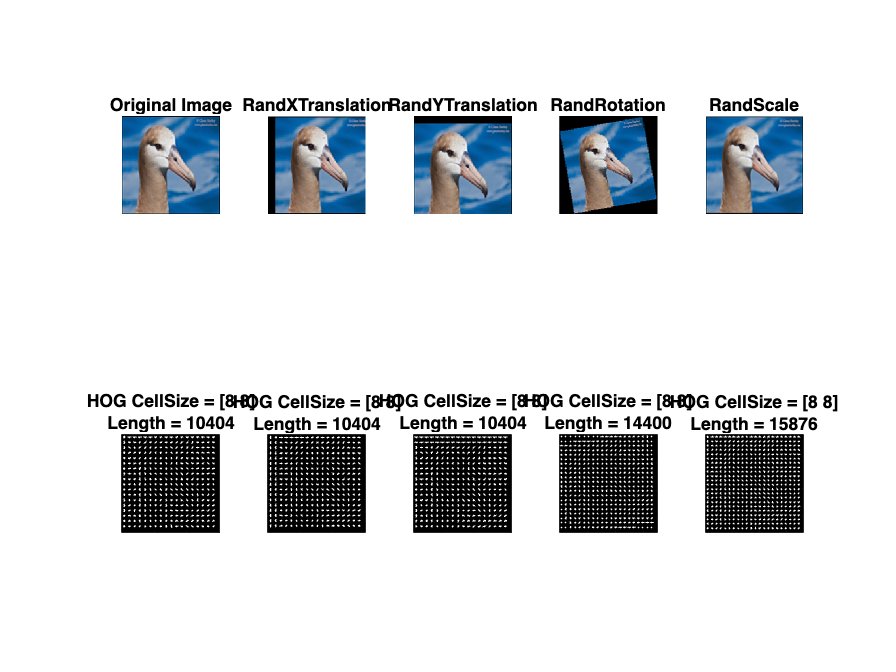

figure(1);
reset(cdsTraining);
img = cdsTraining.read{1};

% Display original image
subplot(2, 5, 1); 
imshow(img);
title('Original Image');

% Display HOG features for original image
[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);
subplot(2, 5, 6);
plot(vis8x8); 
title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

% Apply and display each augmentation manually

% RandXTranslation
translatedImg = imtranslate(img, [10, 0]);  % translate 10 pixels along x-axis
subplot(2, 5, 2); 
imshow(translatedImg);
title('RandXTranslation');

[hog_8x8, vis8x8] = extractHOGFeatures(translatedImg,'CellSize',[8 8]);
subplot(2, 5, 7);
plot(vis8x8); 
title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

% RandYTranslation
translatedImg = imtranslate(img, [0, 10]);  % translate 10 pixels along y-axis
subplot(2, 5, 3); 
imshow(translatedImg);
title('RandYTranslation');

[hog_8x8, vis8x8] = extractHOGFeatures(translatedImg,'CellSize',[8 8]);
subplot(2, 5, 8);
plot(vis8x8); 
title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

% RandRotation
rotatedImg = imrotate(img, 10);  % rotate 10 degrees
subplot(2, 5, 4); 
imshow(rotatedImg);
title('RandRotation');

[hog_8x8, vis8x8] = extractHOGFeatures(rotatedImg,'CellSize',[8 8]);
subplot(2, 5, 9);
plot(vis8x8); 
title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

% RandScale
scaledImg = imresize(img, 1.2);  % scale by 1.2 times
subplot(2, 5, 5); 
imshow(scaledImg);
title('RandScale');

[hog_8x8, vis8x8] = extractHOGFeatures(scaledImg,'CellSize',[8 8]);
subplot(2, 5, 10);
plot(vis8x8); 
title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

## Extract HOG features

cellSize = [32 32];    
[hog_32x32, vis32x32] = extractHOGFeatures(img,'CellSize',[32 32]);
hogFeatureSize = length(hog_32x32);

% Start by extracting HOG features from the training set. These features 
% will be used to train the classifier.
% Loop over the trainingSet and extract HOG features from each image.
% Extract HOG features from the augmented training set
% Loop over the trainingSet and extract HOG features from each image.
numImagesTrain = numel(trainingImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
trainingFeatures = zeros(numImagesTrain, hogFeatureSize, 'single');
reset(cdsTraining);     % Make sure we start with the first image
for i = 1:numImagesTrain
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.    
    imgGray = im2gray(imgFromDS{1});      % Ensure images are grayscale
    
    trainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);  
end


% Extract HOG features from the augmented images as well
augmentedTrainingFeatures = zeros(numImagesTrain, hogFeatureSize, 'single');
reset(augmentedTrainingImageDS);
i = 1;
while hasdata(augmentedTrainingImageDS)  % check if there is data available
    imgFromDS = read(augmentedTrainingImageDS);  % read the data
    imgGray = im2gray(imgFromDS.input{1});  % The 'input' variable contains the images
    
    augmentedTrainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
    i = i + 1;
end


% Concatenate the original HOG features with the features extracted from the augmented images
trainingFeatures = [trainingFeatures; augmentedTrainingFeatures];

% Double the training labels to match the concatenated features
trainingLabels = [trainingImageDS.Labels; trainingImageDS.Labels];

% Now extract HOG features from the test set as well.
numImagesTest = numel(testImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
testFeatures = zeros(numImagesTest, hogFeatureSize, 'single');
reset(cdsTest);     % Make sure we start with the first image
for i = 1:numImagesTest
    imgFromDS = read(cdsTest);    % Get item from datastore
    imgGray = im2gray(imgFromDS{1});  % Ensure images are grayscales
    
    testFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);  
end

## Include color histogram features in feature extraction

numBins = 32; % Number of bins for color histogram
colorHistFeatureSize = 3 * numBins; % Each channel has 'numBins' features

% For training features
trainingFeatures_color = zeros(numImagesTrain, colorHistFeatureSize, 'single');
reset(cdsTraining); 
for i = 1:numImagesTrain
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.    
    imgColor = imgFromDS{1};
    
    trainingFeatures_color(i, :) = computeColorHistFeatures(imgColor, numBins);  
end

% For augmented training features
augmentedTrainingFeatures_color = zeros(numImagesTrain, colorHistFeatureSize, 'single');
reset(augmentedTrainingImageDS);
i = 1;
while hasdata(augmentedTrainingImageDS)  % check if there is data available
    imgFromDS = read(augmentedTrainingImageDS);  % read the data
    imgColor = imgFromDS.input{1};  % The 'input' variable contains the images
    
    augmentedTrainingFeatures_color(i, :) = computeColorHistFeatures(imgColor, numBins);
    i = i + 1;
end

% Concatenate the original color histogram features with the features extracted from the augmented images
trainingFeatures_color = [trainingFeatures_color; augmentedTrainingFeatures_color];

% For test features
testFeatures_color = zeros(numImagesTest, colorHistFeatureSize, 'single');
reset(cdsTest);
for i = 1:numImagesTest
    imgFromDS = read(cdsTest);    % Get item from datastore
    imgColor = imgFromDS{1};
    
    testFeatures_color(i, :) = computeColorHistFeatures(imgColor, numBins);  
end

## Combine HOG features and color histogram features

% Combine HOG features and color histogram features

% Select only the top 50 features
num_selected_features = 50;

trainingFeatures = [trainingFeatures, trainingFeatures_color];
trainingFeatures = trainingFeatures(:, 1:num_selected_features);

testFeatures = [testFeatures, testFeatures_color];
testFeatures = testFeatures(:, 1:num_selected_features);


## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Train a multi-class SVM

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 3 5 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to the parallel pool (number of workers: 10).
Copying objective function to workers...
Done copying objective function to workers.


|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       5 | Accept |     0.99072 |      964.59 |      0.9898 |     0.99037 |    6.245e-09 |
|    2 |       5 | Accept |     0.99001 |      967.58 |      0.9898 |     0.99037 |   0.00012564 |
|    3 |       5 | Accept |     0.99242 |      911.76 |      0.9898 |     0.99037 |        3.965 |
|    4 |       5 | Best   |      0.9898 |      972.48 |      0.9898 |     0.99037 |   8.1809e-09 |
|    5 |       5 | Accept |     0.99065 |      965.21 |      0.9898 |     0.99037 |    2.988e-06 |
|    6 |       5 | Accept |     0.99065 |      967.63 |      0.9898 |     0.99037 |   6.9585e-06 |


|    7 |       7 | Accept |     0.99228 |      1111.6 |      0.9898 |     0.99047 |      0.66953 |
|    8 |       7 | Accept |     0.99029 |      1131.5 |      0.9898 |     0.99047 |   1.3366e-06 |
|    9 |       7 | Accept |     0.99072 |      1142.3 |      0.9898 |     0.99047 |   1.3921e-08 |
|   10 |       7 | Accept |     0.99107 |      1134.1 |      0.9898 |     0.99047 |   6.4128e-07 |
|   11 |      10 | Accept |     0.99256 |      950.34 |      0.9898 |     0.99046 |       1.7742 |
|   12 |       8 | Accept |      0.9915 |      1032.4 |      0.9898 |     0.99047 |    0.0039842 |
|   13 |       8 | Accept |     0.99228 |      1030.9 |      0.9898 |     0.99047 |       1.1542 |
|   14 |       8 | Accept |      0.9927 |      1021.8 |      0.9898 |     0.99047 |       1.1242 |
|   15 |       8 | Accept |     0.99022 |        1052 |      0.9898 |      0.9904 |   1.2735e-09 |
|   16 |      10 | Best   |     0.98966 |      1105.2 |     0.98966 |     0.99003 |   0.00031624 |
|   17 |  

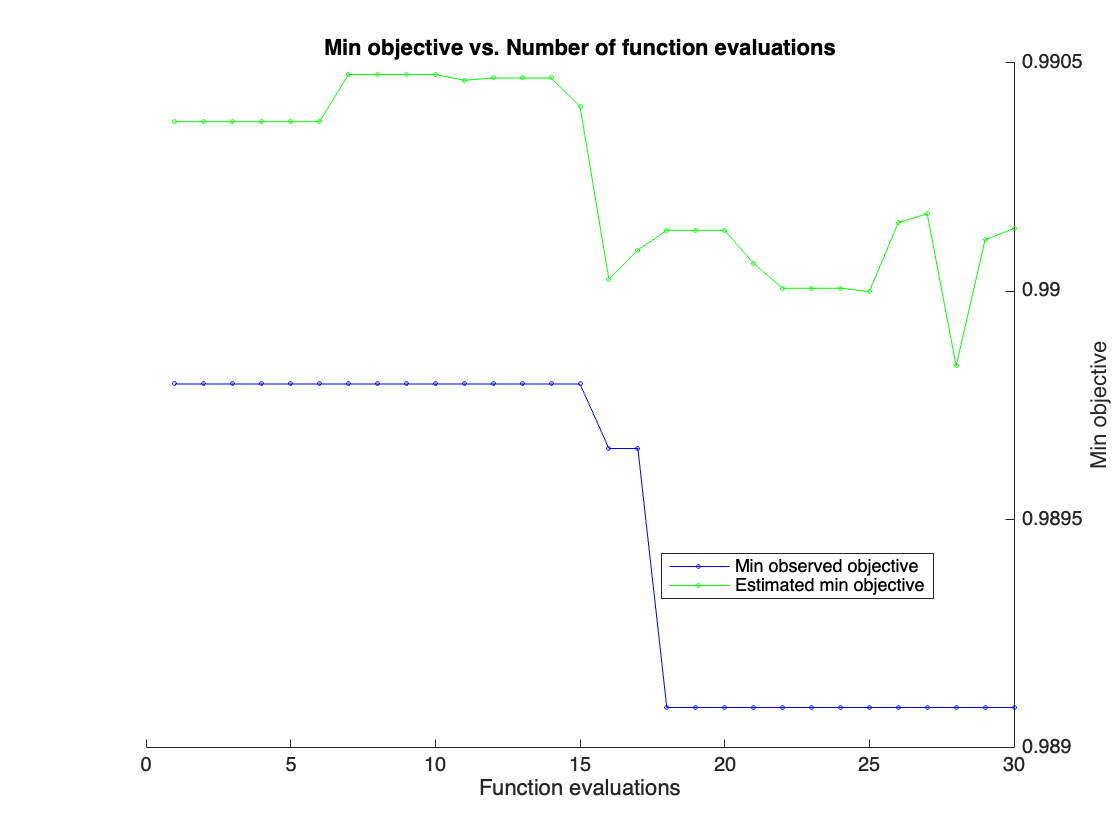

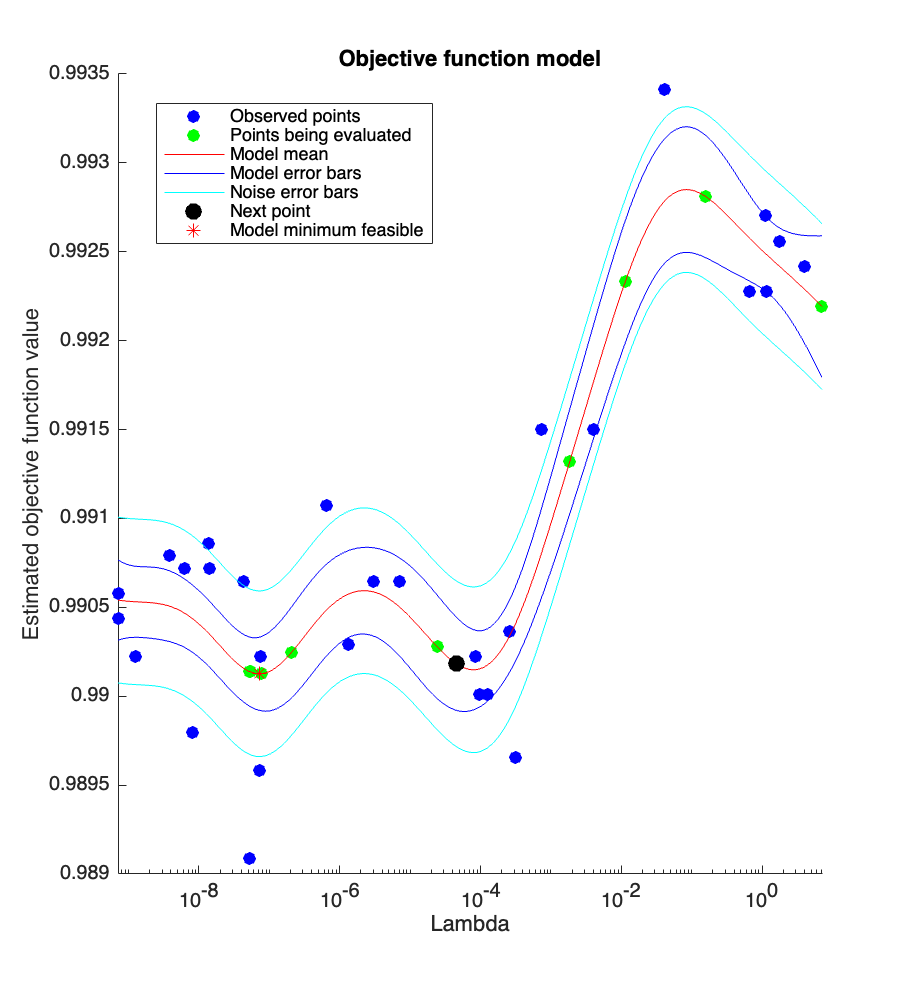


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 3928.8242 seconds
Total objective function evaluation time: 32124.365

Best observed feasible point:
      Lambda  
    __________

    5.3112e-08

Observed objective function value = 0.98909
Estimated objective function value = 0.99014
Function evaluation time = 1142.6005

Best estimated feasible point (according to models):
      Lambda  
    __________

    5.3112e-08

Estimated objective function value = 0.99014
Estimated function evaluation time = 1067.5349



t = templateLinear('Solver', 'dual');
options = struct('UseParallel', true);

% fitcecoc uses multiple SVM learners and a 'One-vs-One' encoding scheme.
Classifier = fitcecoc(trainingFeatures, trainingLabels, 'Learners', t, ...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);

## Test the accuracy on the test partition

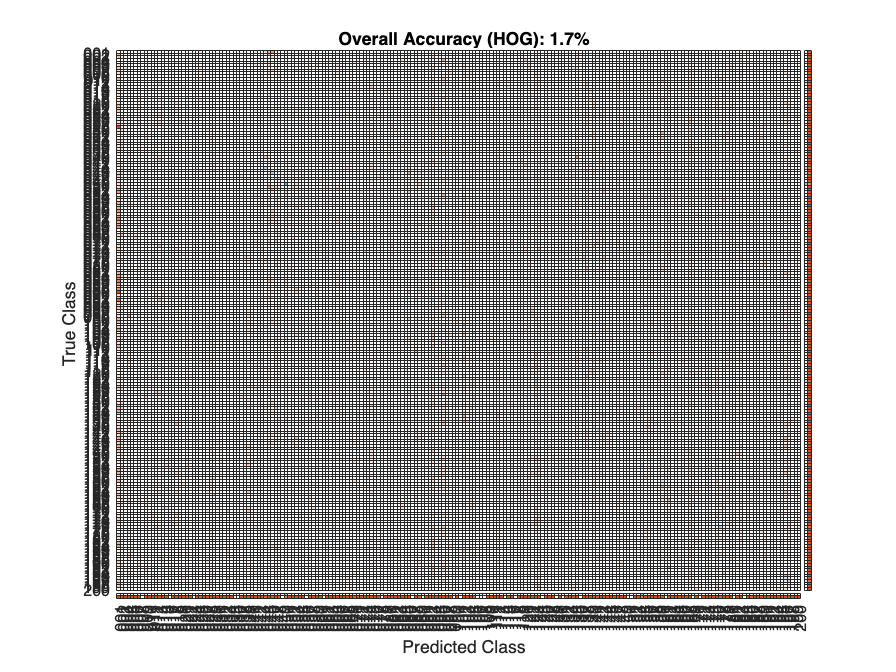

YPred = predict(Classifier, testFeatures);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line

% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (HOG): "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

%% Compute classwise positive recogniton rate
classwisePosRecog = cell(height(order), 2);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog{iI, 1} = order(iI);  % add image name
    classwisePosRecog{iI, 2} = round(100 * m(iI, iI) / samplesPerRow(iI), 1);  % add recognition rate
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog);

    {[001]}    {[      0]}
    {[002]}    {[      0]}
    {[003]}    {[      0]}
    {[004]}    {[      0]}
    {[005]}    {[      0]}
    {[006]}    {[      0]}
    {[007]}    {[      0]}
    {[008]}    {[      0]}
    {[009]}    {[      0]}
    {[010]}    {[      0]}
    {[011]}    {[      0]}
    {[012]}    {[ 9.1000]}
    {[013]}    {[ 8.3000]}
    {[014]}    {[      0]}
    {[015]}    {[      0]}
    {[016]}    {[      0]}
    {[017]}    {[      0]}
    {[018]}    {[      0]}
    {[019]}    {[      0]}
    {[020]}    {[      0]}
    {[021]}    {[ 8.3000]}
    {[022]}    {[      0]}
    {[023]}    {[      0]}
    {[024]}    {[      0]}
    {[025]}    {[ 8.3000]}
    {[026]}    {[      0]}
    {[027]}    {[      0]}
    {[028]}    {[ 8.3000]}
    {[029]}    {[      0]}
    {[030]}    {[      0]}
    {[031]}    {[      0]}
    {[032]}    {[      0]}
    {[033]}    {[      0]}
    {[034]}    {[      0]}
    {[035]}    {[      0]}
    {[036]}    {[      0]}
    {[037]}    {[      0]}
 